% Example Code: Loading Biosemi EEG Data
% Jerry Zhang
% December 2023

% 1. Extract multi-channel EEG data from Biosemi BDF files
% 2. Compute bandpass, bandstop and notch filtered EEG signals
% 3. Segment filtered EEG data
% 4. Compute FFT on EEG segments

## Load File and Extract Data

close all;
clearvars;

% Set directory, get file info and load data
[filename, path] = uigetfile('.\*.bdf');
hdr = read_biosemi_bdf([path filename]);
EEG_raw = read_biosemi_bdf([path filename], hdr, hdr.nSamplesPre, hdr.nSamples)'; % This is from the 'Fieldtrip' toolbox
EEG_events = EEG_raw(2:end, end); % We don't need the event data for now
EEG_raw = EEG_raw(2:end, 1:end-1); % Discard the first garbage value

% Let's just look at a single, occipital channel Oz for now
channel_select = ['A16'];
EEG_Oz1 = EEG_raw(:, find(strcmp(hdr.label,channel_select)));

## Filter EEG Data

% See https://au.mathworks.com/help/signal/ref/butter.html
% Set up 1-40 Hz bandpass filter - 6th order zero-phase Butterworth IIR
Fc_BP = [1 40];
Wn_BP = Fc_BP/(hdr.Fs/2);

[B_BP, A_BP] = butter(3, Wn_BP, 'bandpass');
EEG_Oz_filtered1 = filtfilt(B_BP, A_BP, EEG_Oz1);


## Plot EEG Time-Series - Raw and Filtered

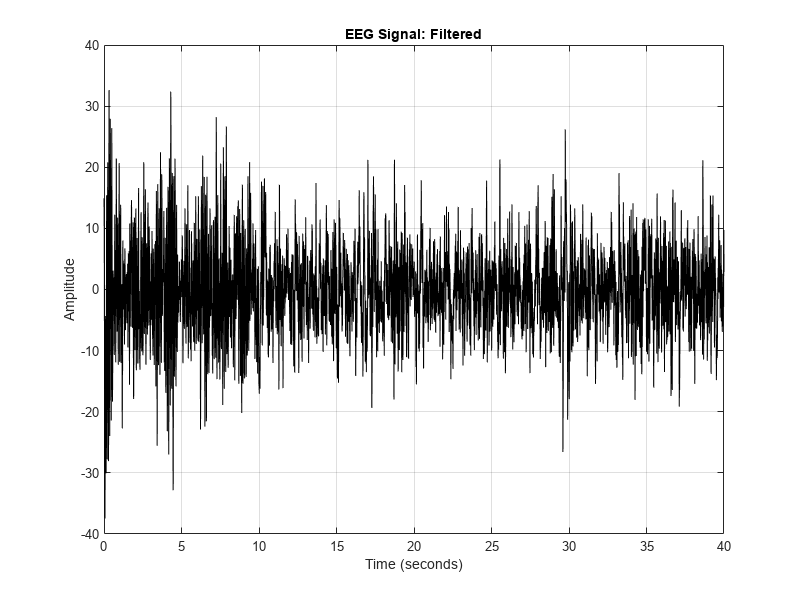

time = (1:length(EEG_Oz_filtered1))/hdr.Fs;
% Plotting
figure('Position', [100, 100, 800, 600]);
plot(time, EEG_Oz_filtered1, 'k');
xlabel('Time (seconds)');
ylabel('Amplitude');
title('EEG Signal: Filtered');
xlim([0 40]);
grid on;

## Segment EEG Data

## Plot and Compare EEG Fourier Spectrums

## **Plot all EEG Signals**

Processing A1_Full_Block.bdf...


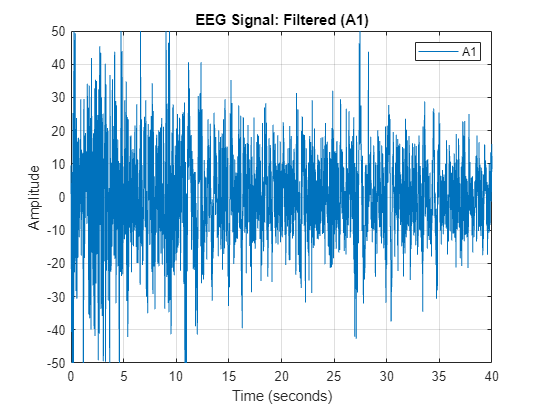

Processing A3_Full_Block.bdf...


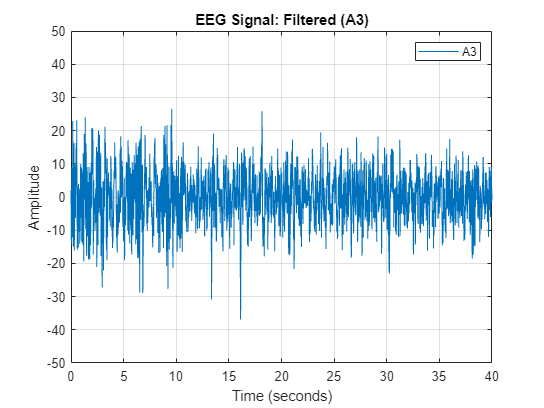

Processing A4_Full_Block.bdf...


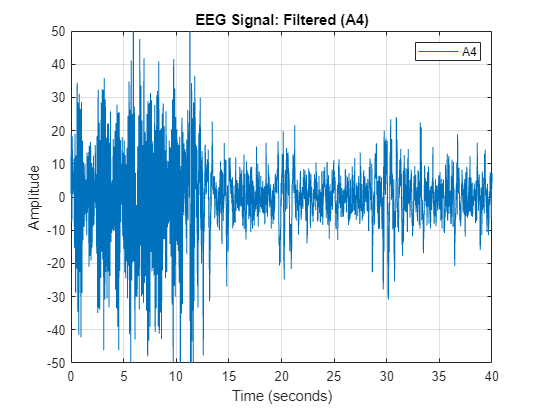

Processing C1_Alpha.bdf...


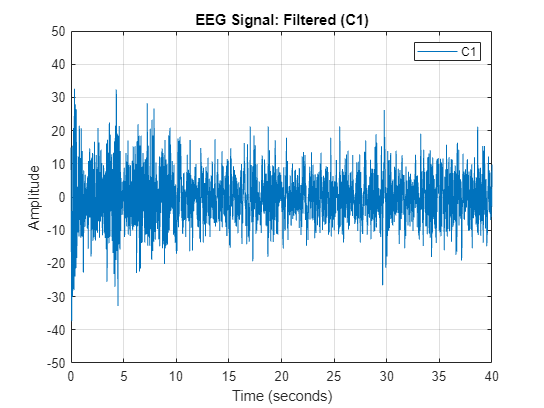

Processing C2_Alpha.bdf...


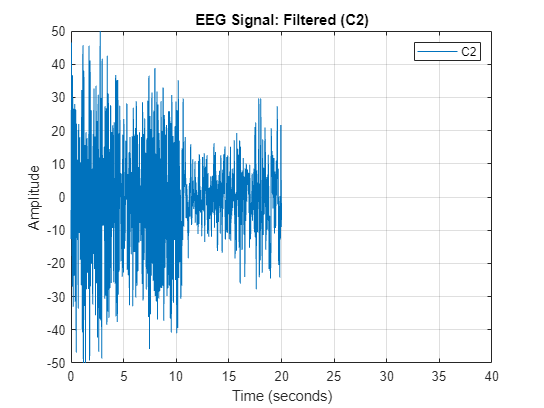

Processing C3_Alpha.bdf...


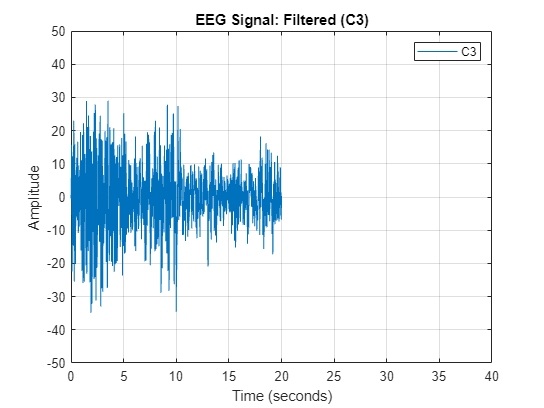

close all;
clearvars;

% Set directory
path = uigetdir(); % Let the user choose the directory
files = dir(fullfile(path, '*.bdf')); % Get info of all .bdf files in the directory

for fileIdx = 1:length(files)
    filename = files(fileIdx).name;
    fprintf('Processing %s...\n', filename);
    
    % Load data
    hdr = read_biosemi_bdf(fullfile(path, filename));
    EEG_raw = read_biosemi_bdf(fullfile(path, filename), hdr, hdr.nSamplesPre, hdr.nSamples)'; 
    EEG_events = EEG_raw(2:end, end); % Discard event data
    EEG_raw = EEG_raw(2:end, 1:end-1); % Discard the first garbage value
    
    % Extract a single channel
    channel_select = 'A16';
    EEG_Oz = EEG_raw(:, find(strcmp(hdr.label, channel_select)));
    
    % Filter EEG Data
    Fc_BP = [1 40];
    Wn_BP = Fc_BP/(hdr.Fs/2);
    [B_BP, A_BP] = butter(3, Wn_BP, 'bandpass');
    EEG_Oz_filtered = filtfilt(B_BP, A_BP, EEG_Oz);
    
    % Dynamically create a variable with the filtered data
    varName = ['EEG_' filename(1:2) '_filtered'];
    assignin('base', varName, EEG_Oz_filtered);
    
    % Create a new figure for each file
    figure;
    figure('Position', [100, 100, 800, 600]);
    time = (1:length(EEG_Oz_filtered))/hdr.Fs;
    plot(time, EEG_Oz_filtered, 'DisplayName', filename(1:2));
    xlabel('Time (seconds)');
    ylabel('Amplitude');
    title(['EEG Signal: Filtered (' filename(1:2) ')']);
    ylim([-50 50]);
    xlim([0 40]);
    grid on;
    legend show;
end


% Each filtered EEG signal is plotted in a separate figure,
% and variables named after the first two initials of each file name followed by '_filtered' are created in the base workspace.

% Find variables that match the pattern 'EEG_Oz...'
ozVarNames = who('EEG_Oz*');

% Loop through each variable name and clear it
for i = 1:length(ozVarNames)
    evalin('base', ['clear ' ozVarNames{i}]);
end

## Segmeting the sections

% Assume Fs is defined; if not, define it based on your data's sampling frequency
Fs = hdr.Fs; % or another way to set Fs if hdr is not available
segmentDuration = 10; % seconds
samplesPerSegment = segmentDuration * Fs;
maxDuration = 40; % Maximum duration to consider in seconds
maxSamples = Fs * maxDuration; % Convert max duration to samples

% Suffixes for each condition
suffixes = {'_EC', '_EO', '_LC', '_RC'};

% Find variables that match the pattern 'EEG_...something'
varNames = who('EEG_*_filtered');

for i = 1:length(varNames)
    % For each variable, segment the data into 10-second intervals within the first 40 seconds
    eegData = eval(varNames{i}); % Get the data for the current variable
    eegData = eegData(1:min(end, maxSamples)); % Limit data to the first 40 seconds
    
    % Calculate number of full segments that can be extracted
    numSegments = min(floor(length(eegData) / samplesPerSegment), length(suffixes));
    
    % Segment and store each segment in a dynamically named variable
    for segIdx = 1:numSegments
        segmentStart = (segIdx-1) * samplesPerSegment + 1;
        segmentEnd = segIdx * samplesPerSegment;
        segmentData = eegData(segmentStart:segmentEnd);
        
        % Create a new variable name for the segment with condition suffix
        segmentVarName = sprintf('%s_segment_%d_%ds%s', varNames{i}, (segIdx-1)*10, segIdx*10, suffixes{segIdx});
        
        % Assign the segment data to the new variable in the base workspace
        assignin('base', segmentVarName, segmentData);
    end
end

% This script segments the first 40 seconds of EEG data into 10-second intervals,
% naming the variables according to the segment time and condition.

## Plotting Power Spectrums for EC (Eyes Closed)

'Plotting Power Spectrums for EC (Eyes Closed)'

ans = 'Plotting Power Spectrums for EC (Eyes Closed)'

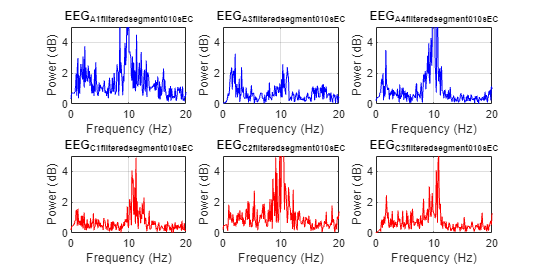

% Find variables with '_EC' suffix for 'EEG_A' and 'EEG_C'
aVarNames = who('EEG_A*_EC');
cVarNames = who('EEG_C*_EC');

% Determine the number of plots needed
numPlots = max(length(aVarNames), length(cVarNames));

% Setup figure with increased size
fig = figure;
fig.Position = [100, 100, 1200, 600]; % Increase figure size

for i = 1:numPlots
    % Plot EEG_A variables
    if i <= length(aVarNames)
        % Retrieve the segment data
        segmentDataA = eval(aVarNames{i});
        
        % Compute the FFT and prepare the power spectrum data
        [f, P1] = computePowerSpectrum(segmentDataA, Fs);
        
        % Plot on the left side
        subplot(2, numPlots, i); % Adjust subplot grid as needed
        plot(f, P1, 'b'); % Example color blue for EEG_A
        title(aVarNames{i});
        xlabel('Frequency (Hz)');
        ylabel('Power (dB)');
        xlim([0 20]);
        ylim([0 5]);
        grid on;
    end
    
    % Plot EEG_C variables
    if i <= length(cVarNames)
        % Retrieve the segment data
        segmentDataC = eval(cVarNames{i});
        
        % Compute the FFT and prepare the power spectrum data
        [f, P1] = computePowerSpectrum(segmentDataC, Fs);
        
        % Plot on the right side
        subplot(2, numPlots, numPlots + i); % Adjust subplot grid as needed
        plot(f, P1, 'r'); % Example color red for EEG_C
        title(cVarNames{i});
        xlabel('Frequency (Hz)');
        ylabel('Power (dB)');
        xlim([0 20]);
        ylim([0 5]);
        grid on;
    end
end

## Plotting Power Spectrums for EO (Eyes Open)

'Plotting Power Spectrums for EO (Eyes Open)'

ans = 'Plotting Power Spectrums for EO (Eyes Open)'

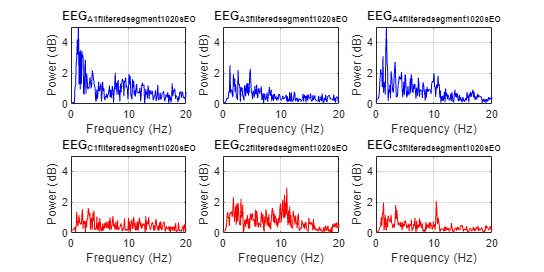

% Find variables with '_EO' suffix for 'EEG_A' and 'EEG_C'
aVarNames = who('EEG_A*_EO');
cVarNames = who('EEG_C*_EO');

% Determine the number of plots needed
numPlots = max(length(aVarNames), length(cVarNames));

% Setup figure with increased size
fig = figure;
fig.Position = [100, 100, 1200, 600]; % Increase figure size

for i = 1:numPlots
    % Plot EEG_A variables
    if i <= length(aVarNames)
        % Retrieve the segment data
        segmentDataA = eval(aVarNames{i});
        
        % Compute the FFT and prepare the power spectrum data
        [f, P1] = computePowerSpectrum(segmentDataA, Fs);
        
        % Plot on the left side
        subplot(2, numPlots, i); % Adjust subplot grid as needed
        plot(f, P1, 'b'); % Example color blue for EEG_A
        title(aVarNames{i});
        xlabel('Frequency (Hz)');
        ylabel('Power (dB)');
        xlim([0 20]);
        ylim([0 5]);
        grid on;
    end
    
    % Plot EEG_C variables
    if i <= length(cVarNames)
        % Retrieve the segment data
        segmentDataC = eval(cVarNames{i});
        
        % Compute the FFT and prepare the power spectrum data
        [f, P1] = computePowerSpectrum(segmentDataC, Fs);
        
        % Plot on the right side
        subplot(2, numPlots, numPlots + i); % Adjust subplot grid as needed
        plot(f, P1, 'r'); % Example color red for EEG_C
        title(cVarNames{i});
        xlabel('Frequency (Hz)');
        ylabel('Power (dB)');
        xlim([0 20]);
        ylim([0 5]);
        grid on;
    end
end

## Plotting Power Spectrums for LC (Left Eye Closed)

'Plotting Power Spectrums for LC (Left Eye Closed)'

ans = 'Plotting Power Spectrums for LC (Left Eye Closed)'

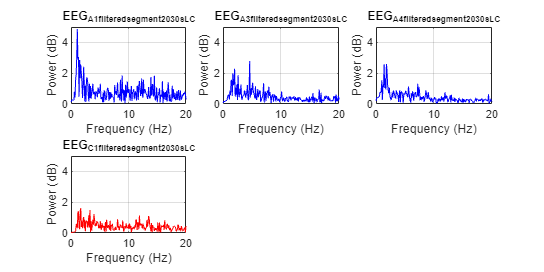

% Find variables with '_LC' suffix for 'EEG_A' and 'EEG_C'
aVarNames = who('EEG_A*_LC');
cVarNames = who('EEG_C*_LC');

% Determine the number of plots needed
numPlots = max(length(aVarNames), length(cVarNames));

% Setup figure with increased size
fig = figure;
fig.Position = [100, 100, 1200, 600]; % Increase figure size

for i = 1:numPlots
    % Plot EEG_A variables
    if i <= length(aVarNames)
        % Retrieve the segment data
        segmentDataA = eval(aVarNames{i});
        
        % Compute the FFT and prepare the power spectrum data
        [f, P1] = computePowerSpectrum(segmentDataA, Fs);
        
        % Plot on the left side
        subplot(2, numPlots, i); % Adjust subplot grid as needed
        plot(f, P1, 'b'); % Example color blue for EEG_A
        title(aVarNames{i});
        xlabel('Frequency (Hz)');
        ylabel('Power (dB)');
        xlim([0 20]);
        ylim([0 5]);
        grid on;
    end
    
    % Plot EEG_C variables
    if i <= length(cVarNames)
        % Retrieve the segment data
        segmentDataC = eval(cVarNames{i});
        
        % Compute the FFT and prepare the power spectrum data
        [f, P1] = computePowerSpectrum(segmentDataC, Fs);
        
        % Plot on the right side
        subplot(2, numPlots, numPlots + i); % Adjust subplot grid as needed
        plot(f, P1, 'r'); % Example color red for EEG_C
        title(cVarNames{i});
        xlabel('Frequency (Hz)');
        ylabel('Power (dB)');
        xlim([0 20]);
        ylim([0 5]);
        grid on;
    end
end

## Plotting Power Spectrums for RC (Right Eye Closed)

'Plotting Power Spectrums for RC (Right Eye Closed)'

ans = 'Plotting Power Spectrums for RC (Right Eye Closed)'

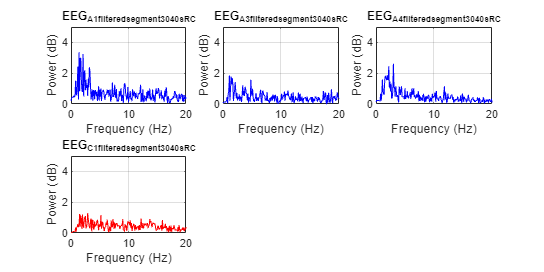

% Find variables with '_RC' suffix for 'EEG_A' and 'EEG_C'
aVarNames = who('EEG_A*_RC');
cVarNames = who('EEG_C*_RC');

% Determine the number of plots needed
numPlots = max(length(aVarNames), length(cVarNames));

% Setup figure with increased size
fig = figure;
fig.Position = [100, 100, 1200, 600]; % Increase figure size

for i = 1:numPlots
    % Plot EEG_A variables
    if i <= length(aVarNames)
        % Retrieve the segment data
        segmentDataA = eval(aVarNames{i});
        
        % Compute the FFT and prepare the power spectrum data
        [f, P1] = computePowerSpectrum(segmentDataA, Fs);
        
        % Plot on the left side
        subplot(2, numPlots, i); % Adjust subplot grid as needed
        plot(f, P1, 'b'); % Example color blue for EEG_A
        title(aVarNames{i});
        xlabel('Frequency (Hz)');
        ylabel('Power (dB)');
        xlim([0 20]);
        ylim([0 5]);
        grid on;
    end
    
    % Plot EEG_C variables
    if i <= length(cVarNames)
        % Retrieve the segment data
        segmentDataC = eval(cVarNames{i});
        
        % Compute the FFT and prepare the power spectrum data
        [f, P1] = computePowerSpectrum(segmentDataC, Fs);
        
        % Plot on the right side
        subplot(2, numPlots, numPlots + i); % Adjust subplot grid as needed
        plot(f, P1, 'r'); % Example color red for EEG_C
        title(cVarNames{i});
        xlabel('Frequency (Hz)');
        ylabel('Power (dB)');
        xlim([0 20]);
        ylim([0 5]);
        grid on;
    end
end

## Average FFT

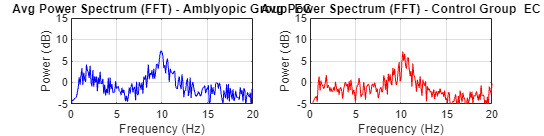

% Define the condition to analyze ('_EC' for Eyes Closed, '_EO' for Eyes Open, '_RC' for Right Eye Closed)
currentCondition = '_EC';  % Change this value as needed

% Construct title suffix based on the condition
conditionTitle = strrep(currentCondition, '_', ' ');  % Remove underscore for display

% Find variables with the current condition suffix for 'EEG_A' and 'EEG_C'
aVarNames = who(['EEG_A*' currentCondition]);
cVarNames = who(['EEG_C*' currentCondition]);

% Initialize sums for averaging
sumPowerA = 0;
sumPowerC = 0;
nA = length(aVarNames);
nC = length(cVarNames);

% Setup figure with increased size
fig = figure;
fig.Position = [100, 100, 1200, 300]; % Adjust figure size for two plots

% Compute averaged power spectrum for EEG_A group
for i = 1:nA
    segmentDataA = eval(aVarNames{i});
    L = length(segmentDataA); % Length of the signal
    fftDataA = fft(segmentDataA);
    P2 = abs(fftDataA/L);
    P1 = P2(1:L/2+1);
    P1(2:end-1) = 2*P1(2:end-1);
    f = Fs*(0:(L/2))/L;
    sumPowerA = sumPowerA + P1; % Sum power spectra
end
avgPowerA = sumPowerA / nA; % Average power spectrum

% Plot averaged power spectrum for EEG_A group
subplot(1, 2, 1); % First subplot for group A
plot(f, 10*log10(avgPowerA), 'b'); % Plot in blue
title(['Avg Power Spectrum (FFT) - Amblyopic Group ' conditionTitle]);
xlabel('Frequency (Hz)');
ylabel('Power (dB)');
xlim([0 20]);
ylim([-5 15]);
grid on;

% Compute averaged power spectrum for EEG_C group
for i = 1:nC
    segmentDataC = eval(cVarNames{i});
    L = length(segmentDataC); % Length of the signal
    fftDataC = fft(segmentDataC);
    P2 = abs(fftDataC/L);
    P1 = P2(1:L/2+1);
    P1(2:end-1) = 2*P1(2:end-1);
    f = Fs*(0:(L/2))/L;
    sumPowerC = sumPowerC + P1; % Sum power spectra
end
avgPowerC = sumPowerC / nC; % Average power spectrum

% Plot averaged power spectrum for EEG_C group
subplot(1, 2, 2); % Second subplot for group C
plot(f, 10*log10(avgPowerC), 'r'); % Plot in red
title(['Avg Power Spectrum (FFT) - Control Group ' conditionTitle]);
xlabel('Frequency (Hz)');
ylabel('Power (dB)');
xlim([0 20]);
ylim([-5 15]);
grid on;

## Average Welch's Method

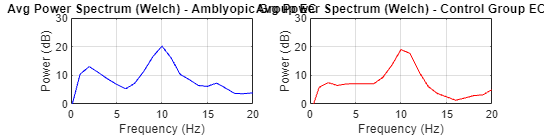

% Define the condition to analyze ('_EC', '_EO', or '_RC')
% currentCondition = '_EC';  % Change this value to '_EC', '_EO', or '_RC' as needed

% Construct title based on the condition
conditionTitle = strrep(currentCondition, '_', '');  % Remove underscore for title

% Find variables with the current condition suffix for 'EEG_A' and 'EEG_C'
aVarNames = who(['EEG_A*' currentCondition]);
cVarNames = who(['EEG_C*' currentCondition]);

% Initialize sums for averaging
sumPowerA = 0;
sumPowerC = 0;
nA = length(aVarNames);
nC = length(cVarNames);

% Setup figure with increased size
fig = figure;
fig.Position = [100, 100, 1200, 300]; % Adjust figure size for two plots

% Compute averaged power spectrum for EEG_A group
for i = 1:nA
    segmentDataA = eval(aVarNames{i});
    [P1, f] = pwelch(segmentDataA, round(Fs), round(Fs/2), [], Fs, 'power');
    sumPowerA = sumPowerA + P1; % Sum power spectra
end
avgPowerA = sumPowerA / nA; % Average power spectrum

% Plot averaged power spectrum for EEG_A group
subplot(1, 2, 1); % First subplot for group A
plot(f, 10*log10(avgPowerA), 'b'); % Plot in blue
title(['Avg Power Spectrum (Welch) - Amblyopic Group ' conditionTitle]);
xlabel('Frequency (Hz)');
ylabel('Power (dB)');
xlim([0 20]);
ylim([0 30]);
grid on;

% Compute averaged power spectrum for EEG_C group
for i = 1:nC
    segmentDataC = eval(cVarNames{i});
    [P1, f] = pwelch(segmentDataC, round(Fs), round(Fs/2), [], Fs, 'power');
    sumPowerC = sumPowerC + P1; % Sum power spectra
end
avgPowerC = sumPowerC / nC; % Average power spectrum

% Plot averaged power spectrum for EEG_C group
subplot(1, 2, 2); % Second subplot for group C
plot(f, 10*log10(avgPowerC), 'r'); % Plot in red
title(['Avg Power Spectrum (Welch) - Control Group ' conditionTitle]);
xlabel('Frequency (Hz)');
ylabel('Power (dB)');
xlim([0 20]);
ylim([0 30]);
grid on;

## Stastistical Analysis

% Define alpha band frequency range
alphaRange = [1 4];

% Find indices of the alpha range in the frequency vector
alphaIndices = find(f >= alphaRange(1) & f <= alphaRange(2));

% Extract alpha band power for each group
alphaPowerA = avgPowerA(alphaIndices);
alphaPowerC = avgPowerC(alphaIndices);

% Convert power to logarithmic scale (dB)
logAlphaPowerA = 10*log10(alphaPowerA);
logAlphaPowerC = 10*log10(alphaPowerC);

% Perform a two-sample t-test assuming unequal variances
[h, p, ci, stats] = ttest2(logAlphaPowerA, logAlphaPowerC, 'Vartype','unequal');

% Check if the test is significant
fprintf('Hypothesis test result (h): %d\n', h);

Hypothesis test result (h): 1


if h == 0
fprintf('The difference between groups is not statistically significant (p >= 0.05).\n');
else
fprintf('The difference between groups is statistically significant (p < 0.05).\n');
end

The difference between groups is statistically significant (p < 0.05).



% Display the results
fprintf('T-test between amblyopic and control groups in the alpha band (8-12 Hz):\n');

T-test between amblyopic and control groups in the alpha band (8-12 Hz):


fprintf('p-value (p): %g\n', p);

p-value (p): 0.0122988


fprintf('Confidence interval on the difference in means (ci): [%g, %g]\n', ci);

Confidence interval on the difference in means (ci): [1.49386, 6.77413]


fprintf('Test statistics (stats): tstat = %g, df = %g, sd = %g\n\n', stats.tstat, stats.df, stats.sd);

Test statistics (stats): tstat = 4.3668, df = 3.95547, sd = 1.75531

Test statistics (stats): tstat = 0.709767, df = 

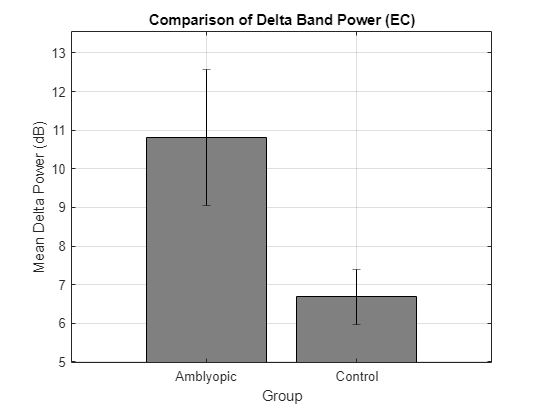


% Example mean alpha power values for each group
meanAlphaPowerA = mean(logAlphaPowerA);
meanAlphaPowerC = mean(logAlphaPowerC);

% Example standard deviation for alpha power values for each group
stdAlphaPowerA = std(logAlphaPowerA);
stdAlphaPowerC = std(logAlphaPowerC);

% Create a figure
figure;

% Define the bar plot data and error bars (standard deviation)
groups = categorical({'Amblyopic', 'Control'});
means = [meanAlphaPowerA, meanAlphaPowerC];
stdDevs = [stdAlphaPowerA, stdAlphaPowerC];

% Create the bar plot with error bars
bar(groups, means, 'FaceColor',[0.5 0.5 0.5]); hold on;
errorbar(groups, means, stdDevs, 'k', 'LineStyle', 'none');

% Add plot labels and title
xlabel('Group');
ylabel('Mean Delta Power (dB)');
title('Comparison of Delta Band Power (EC)');
ylim([min(means-stdDevs)-1, max(means+stdDevs)+1]);

% Show the grid
grid on;

## Time Domain Analysis

% Define the subject groups
amblyopes = {'A1', 'A3', 'A4'};
controls = {'C1', 'C2', 'C3'};

% Initialize arrays to store the average amplitudes
avg_amp_EC_amblyopes = zeros(1, length(amblyopes));
avg_amp_EO_amblyopes = zeros(1, length(amblyopes));
avg_amp_EC_controls = zeros(1, length(controls));
avg_amp_EO_controls = zeros(1, length(controls));

% Calculate average amplitudes for amblyopes
for i = 1:length(amblyopes)
    % Eyes Closed (0-10 seconds)
    var_EC = ['EEG_' amblyopes{i} '_filtered_segment_0_10s_EC'];
    data_EC = eval(var_EC);
    avg_amp_EC_amblyopes(i) = mean(abs(data_EC));

    % Eyes Open (10-20 seconds)
    var_EO = ['EEG_' amblyopes{i} '_filtered_segment_10_20s_EO'];
    data_EO = eval(var_EO);
    avg_amp_EO_amblyopes(i) = mean(abs(data_EO));
end

% Calculate average amplitudes for controls
for i = 1:length(controls)
    % Eyes Closed (0-10 seconds)
    var_EC = ['EEG_' controls{i} '_filtered_segment_0_10s_EC'];  % Fixed parentheses here
    data_EC = eval(var_EC);
    avg_amp_EC_controls(i) = mean(abs(data_EC));

    % Eyes Open (10-20 seconds)
    var_EO = ['EEG_' controls{i} '_filtered_segment_10_20s_EO'];  % Fixed parentheses here
    data_EO = eval(var_EO);
    avg_amp_EO_controls(i) = mean(abs(data_EO));
end

% Calculate the ratio of EC/EO for each group
ratio_amblyopes = avg_amp_EC_amblyopes ./ avg_amp_EO_amblyopes;
ratio_controls = avg_amp_EC_controls ./ avg_amp_EO_controls;

% Statistical Analysis: Using a t-test to compare the ratios between groups
[h, p] = ttest2(ratio_amblyopes, ratio_controls);

% Display results
disp('Ratio of average amplitudes (EC/EO) for Amblyopes:');

Ratio of average amplitudes (EC/EO) for Amblyopes:


disp(ratio_amblyopes);

    1.3834    1.3575    1.8849



disp('Ratio of average amplitudes (EC/EO) for Controls:');

Ratio of average amplitudes (EC/EO) for Controls:


disp(ratio_controls);

    1.5563    2.1064    1.8940



disp(['p-value from t-test comparing the two groups: ', num2str(p)]);

p-value from t-test comparing the two groups: 0.25682


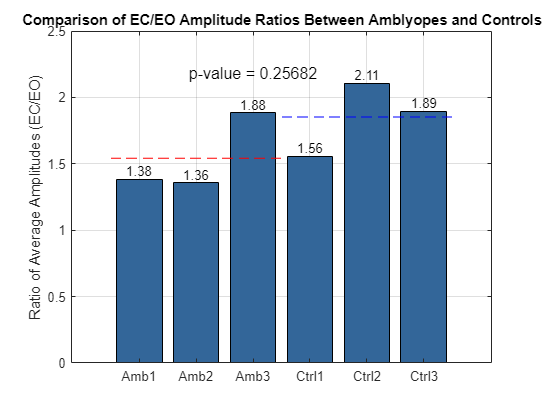


% Define labels for the groups
groupLabels = {'Amb1', 'Amb2', 'Amb3', 'Ctrl1', 'Ctrl2', 'Ctrl3'};

% Combine the ratio data from both groups for plotting
combinedRatios = [ratio_amblyopes ratio_controls];

% Create a bar graph
figure; % Create a new figure window
bar(combinedRatios, 'FaceColor', [0.2, 0.4, 0.6]); % Draw bar graph with a custom color
set(gca, 'XTickLabel', groupLabels, 'XTick', 1:length(combinedRatios)); % Set custom x-axis tick labels
ylabel('Ratio of Average Amplitudes (EC/EO)'); % Label y-axis
title('Comparison of EC/EO Amplitude Ratios Between Amblyopes and Controls'); % Title for the graph
grid on; % Turn on grid for easier readability

% Display the p-value from the statistical test on the graph
hold on; % Keep the current bar graph
text(length(combinedRatios)/2, max(combinedRatios), ['p-value = ' num2str(p)], 'HorizontalAlignment', 'center', 'VerticalAlignment', 'bottom', 'FontSize', 12); % Display p-value text

% Make the graph more informative by adding labels or annotations
for i = 1:length(combinedRatios)
    text(i, combinedRatios(i), sprintf('%.2f', combinedRatios(i)), 'HorizontalAlignment', 'center', 'VerticalAlignment', 'bottom', 'FontSize', 10); % Annotate each bar with its value
end

% Optionally, you can also highlight the difference in means
mean_amblyopes = mean(ratio_amblyopes);
mean_controls = mean(ratio_controls);
plot([0.5, 3.5], [mean_amblyopes, mean_amblyopes], 'r--'); % Line for mean amblyope ratio
plot([3.5, 6.5], [mean_controls, mean_controls], 'b--'); % Line for mean control ratio

hold off; % Release the hold on the current figure

## Spectogram

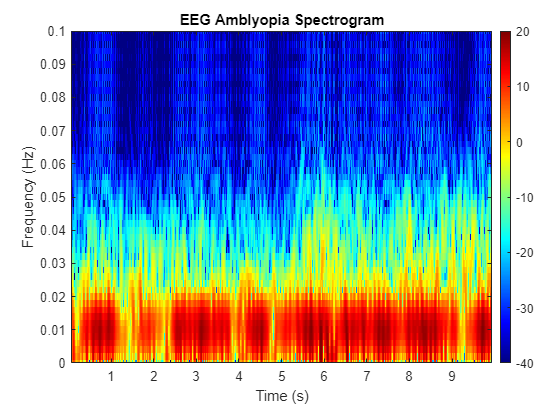

% Assume EEG_signal1 and EEG_signal2 are your EEG data arrays
% Fs is the sampling frequency

% Parameters for the spectrogram
windowLength = 256; % Window length for the spectrogram
nOverlap = 250;     % Number of overlapping samples
nFFT = 1024;         % Number of FFT points

% Setup figure for plotting two spectrograms side by side
figure;
colormap jet; % Set a colormap that offers good contrast

% First Signal Spectrogram

spectrogram(EEG_A4_filtered_segment_0_10s_EC, windowLength, nOverlap, nFFT, Fs, 'yaxis');
title('EEG Amblyopia Spectrogram');
xlabel('Time (s)');
ylabel('Frequency (Hz)');
ylim([0 0.1]);
caxis([-40 20]); % Adjust color axis for consistent scale across subplots

% Enhance with colorbar to interpret power levels
colorbar('Position', [0.92 0.11 0.02 0.815]);

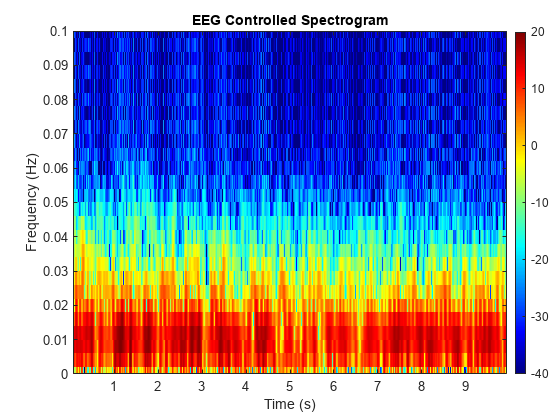

% Assume EEG_signal1 and EEG_signal2 are your EEG data arrays
% Fs is the sampling frequency

% Parameters for the spectrogram
windowLength = 256; % Window length for the spectrogram
nOverlap = 250;     % Number of overlapping samples
nFFT = 512;         % Number of FFT points

% Setup figure for plotting two spectrograms side by side
figure;
colormap jet; % Set a colormap that offers good contrast

% Second Signal Spectrogram
spectrogram(EEG_C2_filtered_segment_0_10s_EC, windowLength, nOverlap, nFFT, Fs, 'yaxis');
title('EEG Controlled Spectrogram');
xlabel('Time (s)');
ylabel('Frequency (Hz)');
ylim([0 0.1]);
caxis([-40 20]); % Adjust color axis for consistent scale across subplots

% Enhance with colorbar to interpret power levels
colorbar('Position', [0.92 0.11 0.02 0.815]);

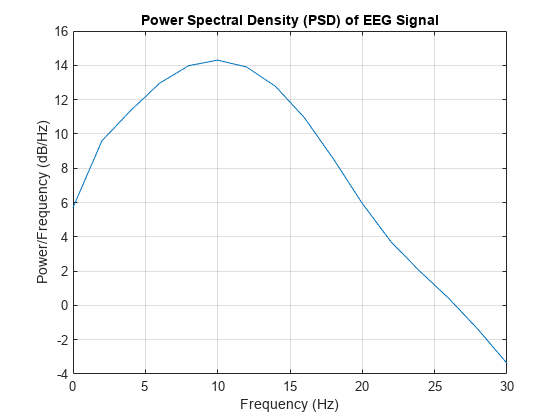

% EEG_signal is your EEG data.
% Fs is the sampling frequency.

% Calculate the Power Spectral Density using the Welch method
[pxx, f] = pwelch(EEG_C2_filtered_segment_0_10s_EC, hamming(256), 128, 1024, Fs);

% Plot the Power Spectral Density
figure;
plot(f, 10*log10(pxx)); % Convert power to dB for visualization
xlabel('Frequency (Hz)');
ylabel('Power/Frequency (dB/Hz)');
title('Power Spectral Density (PSD) of EEG Signal');
xlim([0 30]);
grid on;

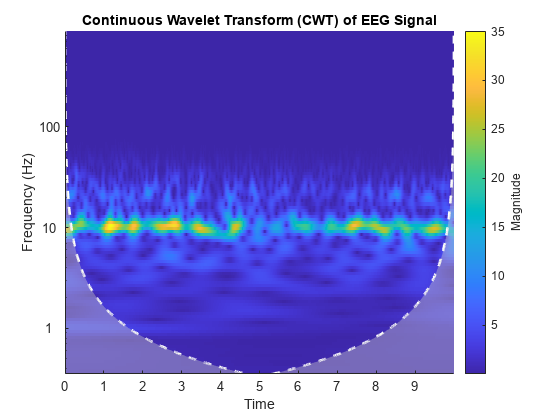

% Assume EEG_signal is your data, and Fs is the sampling frequency
% EEG_signal = ...; % Your EEG data here
% Fs = ...; % Sampling frequency

% Perform the Continuous Wavelet Transform (CWT)
[wt, f] = cwt(EEG_C2_filtered_segment_0_10s_EC, Fs);

% Plot the CWT
figure;
cwt(EEG_C2_filtered_segment_0_10s_EC, Fs);
title('Continuous Wavelet Transform (CWT) of EEG Signal');
xlabel('Time');
ylabel('Frequency (Hz)');

% Assuming EEG_signal1 and EEG_signal2 are your data and Fs is the sampling frequency
EEG_signal1 = EEG_A4_filtered_segment_0_10s_EC

EEG_signal1 =     1.0524
    1.8566
    2.6623
    3.4667
    4.2673
    5.0616
    5.8470
    6.6215
    7.3830
    8.1295


EEG_signal2 = EEG_C3_filtered_segment_0_10s_EC

EEG_signal2 =     0.7764
    0.6480
    0.5176
    0.3880
    0.2616
    0.1410
    0.0281
   -0.0751
   -0.1672
   -0.2471


% Time Domain Features
mean1 = mean(EEG_signal1);
std1 = std(EEG_signal1);
max1 = max(EEG_signal1);
min1 = min(EEG_signal1);
mad1 = mad(EEG_signal1, 1);

mean2 = mean(EEG_signal2);
std2 = std(EEG_signal2);
max2 = max(EEG_signal2);
min2 = min(EEG_signal2);
mad2 = mad(EEG_signal2, 1);

% Frequency Domain Features
% Calculating Power Spectral Density (PSD) using Welch's method
[psd1, freq1] = pwelch(EEG_signal1, hamming(256), 128, 512, Fs);
[psd2, freq2] = pwelch(EEG_signal2, hamming(256), 128, 512, Fs);

% Identifying PSD peaks (dominant frequencies)
[peakPsd1, peakFreqIndex1] = max(psd1);
peakFreq1 = freq1(peakFreqIndex1);
[peakPsd2, peakFreqIndex2] = max(psd2);
peakFreq2 = freq2(peakFreqIndex2);

% Spectral Entropy
entropy1 = wentropy(psd1,'shannon');
entropy2 = wentropy(psd2,'shannon');

% Example of Band Power in Alpha Band (8-12 Hz)
alphaRange = [8 12];
alphaIndex1 = freq1 >= alphaRange(1) & freq1 <= alphaRange(2);
alphaPower1 = bandpower(psd1(freq1), freq1(alphaIndex1), alphaRange, 'psd');

Array indices must be positive integers or logical values.

alphaIndex2 = freq2 >= alphaRange(1) & freq2 <= alphaRange(2);
alphaPower2 = bandpower(psd2(freq2), freq2(alphaIndex2), alphaRange, 'psd');

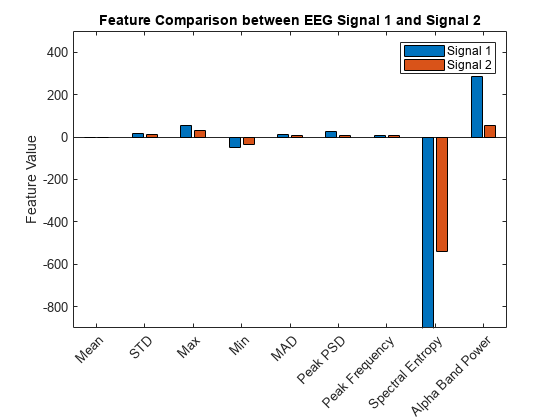

% Assuming EEG_signal1 and EEG_signal2 are your EEG data arrays
% Fs is the sampling frequency

% Corrected calculation of the band power in the alpha band (8-12 Hz)
alphaRange = [8 12]; % Alpha band range in Hz

% Calculate alpha band power directly from the EEG signal
alphaPower1 = bandpower(EEG_signal1, Fs, alphaRange);
alphaPower2 = bandpower(EEG_signal2, Fs, alphaRange);

% Continue with other feature extractions as before
% Frequency Domain Features using Welch's method
[psd1, freq1] = pwelch(EEG_signal1, hamming(256), 128, 512, Fs);
[psd2, freq2] = pwelch(EEG_signal2, hamming(256), 128, 512, Fs);

% Identifying PSD peaks
[peakPsd1, peakFreqIndex1] = max(psd1);
peakFreq1 = freq1(peakFreqIndex1);
[peakPsd2, peakFreqIndex2] = max(psd2);
peakFreq2 = freq2(peakFreqIndex2);

% Spectral Entropy
entropy1 = wentropy(psd1,'shannon');
entropy2 = wentropy(psd2,'shannon');

% Corrected Band Power Calculation
alphaPower1 = bandpower(EEG_signal1, Fs, alphaRange);
alphaPower2 = bandpower(EEG_signal2, Fs, alphaRange);

% Now, alphaPower1 and alphaPower2 are correctly defined, and you can proceed with the comparison as intended.


% Create a table or matrix of features for visualization
features1 = [mean1; std1; max1; min1; mad1; peakPsd1; peakFreq1; entropy1; alphaPower1];
features2 = [mean2; std2; max2; min2; mad2; peakPsd2; peakFreq2; entropy2; alphaPower2];
featureNames = {'Mean', 'STD', 'Max', 'Min', 'MAD', 'Peak PSD', 'Peak Frequency', 'Spectral Entropy', 'Alpha Band Power'};

% Plotting for comparison (simple bar plot for an example)
figure;
bar([features1, features2]);
set(gca, 'xticklabel', featureNames, 'XTickLabelRotation', 45);
legend({'Signal 1', 'Signal 2'});
title('Feature Comparison between EEG Signal 1 and Signal 2');
ylim([-900 500])
ylabel('Feature Value');

## Calculate Power Spectral Ratio (EC)

% Assuming 'Fs' is the sampling frequency
% Define frequency bands
deltaBand = [0.5, 4];
thetaBand = [4, 8];
alphaBand = [8, 13];
betaBand = [13, 30];

% Find all EEG_*_EC variables
ecVarNames = who('*_EC');
for i = 1:length(ecVarNames)
    % Load segment data
    segmentData = eval(ecVarNames{i});
    
    % Compute FFT and single-sided spectrum
    N = length(segmentData);
    fftSegment = fft(segmentData);
    P2 = abs(fftSegment / N);
    P1 = P2(1:N/2+1);
    P1(2:end-1) = 2*P1(2:end-1);
    f = Fs*(0:(N/2))/N;
    
    % Calculate the Spectral Power Ratio
    spr = calculateSpectralPowerRatio(f, P1, deltaBand, thetaBand, alphaBand, betaBand);
    
    % Display the SPR for each segment
    fprintf('%s Spectral Power Ratio: %f\n', ecVarNames{i}, spr);
end

EEG_A1_filtered_segment_0_10s_EC Spectral Power Ratio: 2.299616
EEG_A3_filtered_segment_0_10s_EC Spectral Power Ratio: 1.777787
EEG_A4_filtered_segment_0_10s_EC Spectral Power Ratio: 3.073288
EEG_C1_filtered_segment_0_10s_EC Spectral Power Ratio: 2.601252
EEG_C2_filtered_segment_0_10s_EC Spectral Power Ratio: 2.773377
EEG_C3_filtered_segment_0_10s_EC Spectral Power Ratio: 2.400608



% Function to calculate the Spectral Power Ratio


## Calculate Power Spectral Ratio (EO)

% Assuming 'Fs' is the sampling frequency
% Define frequency bands
deltaBand = [0.5, 4];
thetaBand = [4, 8];
alphaBand = [8, 13];
betaBand = [13, 30];

% Find all EEG_*_EO variables
ecVarNames = who('*_EO');
for i = 1:length(ecVarNames)
    % Load segment data
    segmentData = eval(ecVarNames{i});
    
    % Compute FFT and single-sided spectrum
    N = length(segmentData);
    fftSegment = fft(segmentData);
    P2 = abs(fftSegment / N);
    P1 = P2(1:N/2+1);
    P1(2:end-1) = 2*P1(2:end-1);
    f = Fs*(0:(N/2))/N;
    
    % Calculate the Spectral Power Ratio
    spr = calculateSpectralPowerRatio(f, P1, deltaBand, thetaBand, alphaBand, betaBand);
    
    % Display the SPR for each segment
    fprintf('%s Spectral Power Ratio: %f\n', ecVarNames{i}, spr);
end

EEG_A1_filtered_segment_10_20s_EO Spectral Power Ratio: 1.345901
EEG_A3_filtered_segment_10_20s_EO Spectral Power Ratio: 1.038016
EEG_A4_filtered_segment_10_20s_EO Spectral Power Ratio: 1.209660
EEG_C1_filtered_segment_10_20s_EO Spectral Power Ratio: 1.540800
EEG_C2_filtered_segment_10_20s_EO Spectral Power Ratio: 1.456417
EEG_C3_filtered_segment_10_20s_EO Spectral Power Ratio: 1.310622



% Function to calculate the Spectral Power Ratio

## Calculate Power Spectral Ratio (LC)

% Assuming 'Fs' is the sampling frequency
% Define frequency bands
deltaBand = [0.5, 4];
thetaBand = [4, 8];
alphaBand = [8, 13];
betaBand = [13, 30];

% Find all EEG_*_LC variables
ecVarNames = who('*_LC');
for i = 1:length(ecVarNames)
    % Load segment data
    segmentData = eval(ecVarNames{i});
    
    % Compute FFT and single-sided spectrum
    N = length(segmentData);
    fftSegment = fft(segmentData);
    P2 = abs(fftSegment / N);
    P1 = P2(1:N/2+1);
    P1(2:end-1) = 2*P1(2:end-1);
    f = Fs*(0:(N/2))/N;
    
    % Calculate the Spectral Power Ratio
    spr = calculateSpectralPowerRatio(f, P1, deltaBand, thetaBand, alphaBand, betaBand);
    
    % Display the SPR for each segment
    fprintf('%s Spectral Power Ratio: %f\n', ecVarNames{i}, spr);
end

EEG_A1_filtered_segment_20_30s_LC Spectral Power Ratio: 1.738705
EEG_A3_filtered_segment_20_30s_LC Spectral Power Ratio: 1.034216
EEG_A4_filtered_segment_20_30s_LC Spectral Power Ratio: 0.939911
EEG_C1_filtered_segment_20_30s_LC Spectral Power Ratio: 1.732311



% Function to calculate the Spectral Power Ratio

## Calculate Power Spectral Ratio (RC)

% Assuming 'Fs' is the sampling frequency
% Define frequency bands
deltaBand = [0.5, 4];
thetaBand = [4, 8];
alphaBand = [8, 13];
betaBand = [13, 30];

% Find all EEG_*_RC variables
ecVarNames = who('*_RC');
for i = 1:length(ecVarNames)
    % Load segment data
    segmentData = eval(ecVarNames{i});
    
    % Compute FFT and single-sided spectrum
    N = length(segmentData);
    fftSegment = fft(segmentData);
    P2 = abs(fftSegment / N);
    P1 = P2(1:N/2+1);
    P1(2:end-1) = 2*P1(2:end-1);
    f = Fs*(0:(N/2))/N;
    
    % Calculate the Spectral Power Ratio
    spr = calculateSpectralPowerRatio(f, P1, deltaBand, thetaBand, alphaBand, betaBand);
    
    % Display the SPR for each segment
    fprintf('%s Spectral Power Ratio: %f\n', ecVarNames{i}, spr);
end

EEG_A1_filtered_segment_30_40s_RC Spectral Power Ratio: 1.430458
EEG_A3_filtered_segment_30_40s_RC Spectral Power Ratio: 1.466755
EEG_A4_filtered_segment_30_40s_RC Spectral Power Ratio: 0.995012
EEG_C1_filtered_segment_30_40s_RC Spectral Power Ratio: 1.899153



% Function to calculate the Spectral Power Ratio

function spr = calculateSpectralPowerRatio(f, P1, deltaBand, thetaBand, alphaBand, betaBand)
    % Logical indices for each band
    deltaIdx = f >= deltaBand(1) & f <= deltaBand(2);
    thetaIdx = f >= thetaBand(1) & f <= thetaBand(2);
    alphaIdx = f >= alphaBand(1) & f <= alphaBand(2);
    betaIdx = f >= betaBand(1) & f <= betaBand(2);
    
    % Calculate power in each band
    deltaPower = sum(P1(deltaIdx));
    thetaPower = sum(P1(thetaIdx));
    alphaPower = sum(P1(alphaIdx));
    betaPower = sum(P1(betaIdx));
    
    % Compute SPR
    spr = (alphaPower + betaPower) / (deltaPower + thetaPower);
end

function [f, P1] = computePowerSpectrum(segmentData, Fs)
    N = length(segmentData);
    fftSegment = fft(segmentData);
    P2 = abs(fftSegment / N);
    P1 = P2(1:N/2+1);
    P1(2:end-1) = 2*P1(2:end-1);
    f = Fs*(0:(N/2))/N;
end
